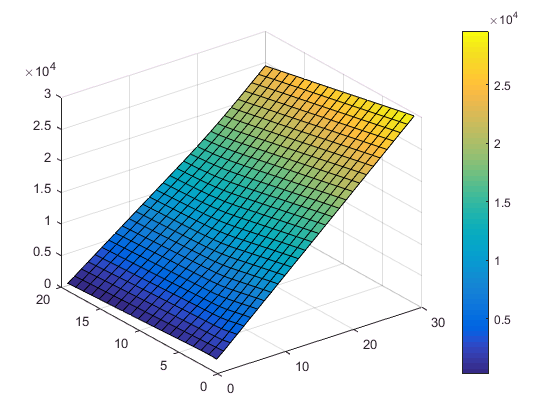

syms x y z1 z2 z3%x代表acumulator，y代表cell
pbuyL=-0.4777;
pbuyH=-0.9897;
pbuyVH=-1.2877;
psell=0.7977;
R2=0.33;R3=0.27;R4=0.40;
X=[1:1:20];
Y=[1:1:30];
cel=xlsread('C:\Users\dell\Desktop\JK\second\2018-8-23-calculate.xlsx',1,'D3:D27')*100;
acc=xlsread('C:\Users\dell\Desktop\JK\second\2018-8-23-calculate.xlsx',1,'B3:B27')*33;
A=ones(length(X),length(Y));
B=ones(length(X),length(Y));
for k=1:1:length(Y)
    y=Y(k);
    for j=1:1:length(X)
        x=X(j);
        temp=0;
        z1=0;
        for i=1:1:25
                a=(99+acc(i).*x)*pbuyL;
                bt=(x*acc(i)+cel(i)*y*R2-29.7);
            if bt>=0
                b=bt*psell;
            else
                b=-bt*pbuyH;
            end    
    %
                ct=(x*acc(i)+19.8-cel(i)*y*R3);
            if ct>=0
                c=ct*pbuyL;
            else
                c=-ct*psell;
            end
            %
                dt1=(x*acc(i)+y*cel(i)*R4);
                dt2=(x*acc(i));
                dt3=(y*cel(i)*R4);
            if dt1>=89.1&&dt2>=29.7
                d=(dt1-89.1)*psell;
            elseif dt1>=89.1&&19.8<=dt2&&dt2<29.7
                d=(29.7-dt2)*pbuyH+(dt3-59.4)*psell;
            elseif dt1>=89.1&&dt2<19.8;
                d=(dt3-59.4)*psell+(19.8-dt2)*pbuyVH+9.9*pbuyH;
            elseif dt1<89.1&&dt2>=19.8
                d=(89.1-dt1)*pbuyH;
            elseif dt1<89.1&&dt2<19.8&&dt3>59.4
                d=dt3*psell+(19.8-dt2)*pbuyVH+9.9*pbuyH;
            end  
            a+b+c+d;
            z1=z1+a+b+c+d;
            temp=temp+a+b+c+d-((99+19.8)*pbuyL+(29.7+59.4+9.9)*pbuyH+19.8*pbuyVH);
            if temp<(480*x+800*y)
                B(j,k)=i;
            end
        end%25年循环
        z1;%上网电费
        z2=-((99+19.8)*pbuyL+(29.7+59.4+9.9)*pbuyH+19.8*pbuyVH)*25;%负载电费
        z3=-(480*x+800*y);%安装费用
        zt=z1+z2+z3;
        A(j,k)=zt;
        B(j,k)=B(j,k)+1;
    end
end
A;
B;
surf(Y,X,A)
colorbar

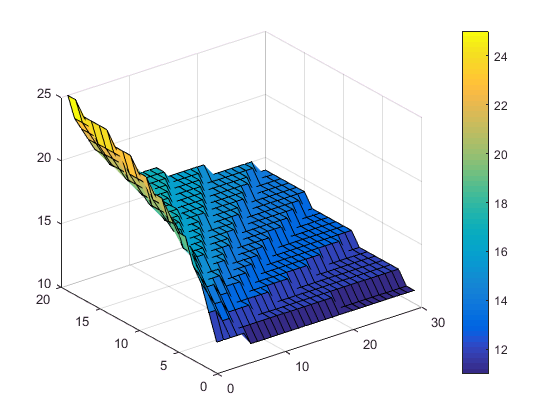

cel =    98.7500
   97.1355
   96.4065
   95.6775
   94.9485
   94.2195
   93.4905
   92.7615
   92.0325
   91.3035


acc =    31.3500
   29.7825
   28.2934
   26.8787
   25.5348
   24.2580
   23.0451
   21.8929
   20.7982
   31.3500


surf(Y,X,B)
colorbar